clear
load Data\data4.mat
n=length(data.CzasLokalnyUTC0100)

n = 3601

data.CzasLokalnyUTC0100(1:4)

ans = 4×1 datetime array
   17/06/2024 11:30:00
   17/06/2024 11:31:00
   17/06/2024 11:32:00
   17/06/2024 11:33:00


data.CzasLokalnyUTC0100(n-3:n)

ans = 4×1 datetime array
   19/06/2024 23:27:00
   19/06/2024 23:28:00
   19/06/2024 23:29:00
   19/06/2024 23:30:00


T=60; %[s]
fs=1/T; %[Hz]
t=T*(0:n-1);

Kompresor=data.StanKompresor;
StanCzujnikaZamkniecia=data.StanCzujnikZamkniciaDrzwi;

TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
TemperatureSterujaca=0.1*data.TemperaturaSterujca;

X=[Kompresor,StanCzujnikaZamkniecia,...
    TemperaturaOtoczenia,TemperatureSterujaca]';

[dataWithoutNans,nan_indices]  = GetRidOfNans(X);
find(nan_indices,~0)


ans =

  0×1 empty double column vector



no nans

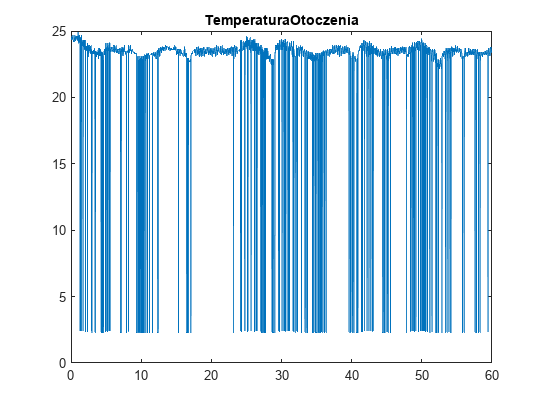

plot(t/(60*60),X(3,:))
title('TemperaturaOtoczenia')

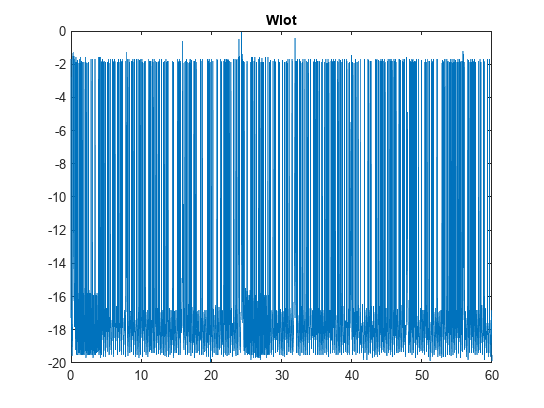

plot(t/(60*60),X(4,:))
title('Wlot')

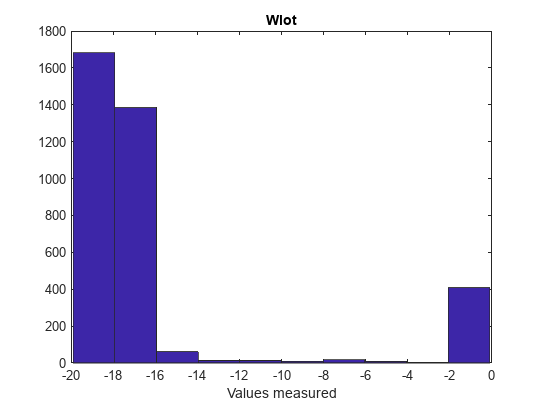

hist(X(4,:))
title('Wlot')
xlabel('Values measured')

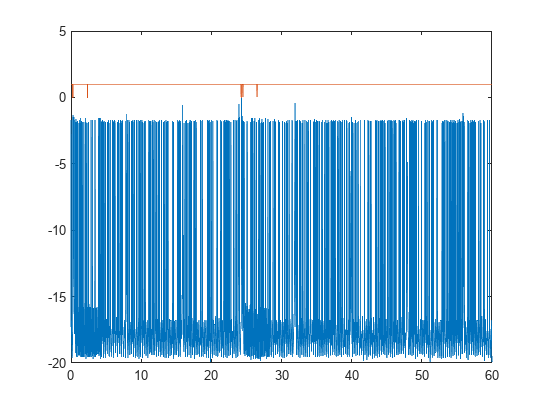

plot(t/(60*60),X(4,:))
hold on
plot(t/(60*60),X(2,:));hold off

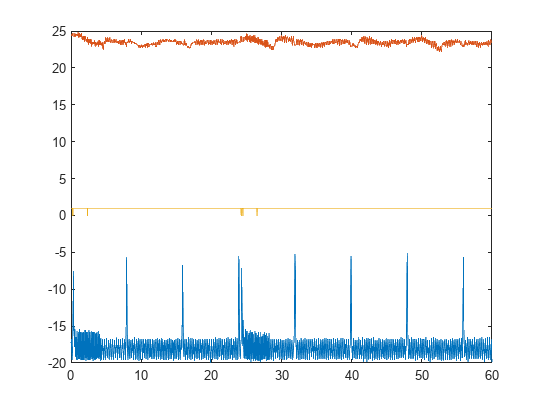

X_toFilter=X(3:4,:);
threshold=[0,5;-5,5];
for i = 1:2
X_filtered(i,:) = InterpolateData(X_toFilter(i,:),threshold(i,:),t);
end

plot(t/(60*60),X_filtered(2,:))
hold on
plot(t/(60*60),X_filtered(1,:))
plot(t/(60*60),X(2,:));hold off

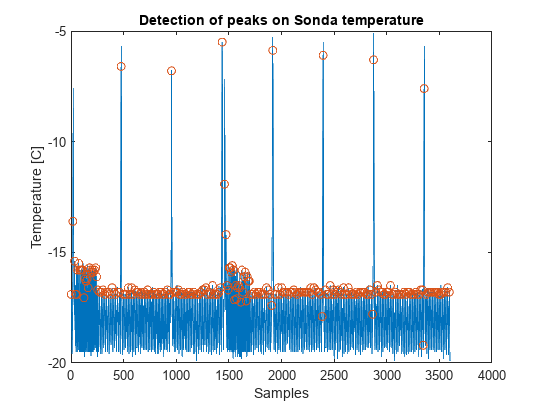

locs=compressorCycles(X(1,:));
x = FeatureExtract(X_filtered(2,:),locs);
plot((X_filtered(2,:)));hold on
plot(locs,(X_filtered(2,locs)),'o');hold off
title('Detection of peaks on Sonda temperature')
xlabel('Samples')
ylabel('Temperature [C]')

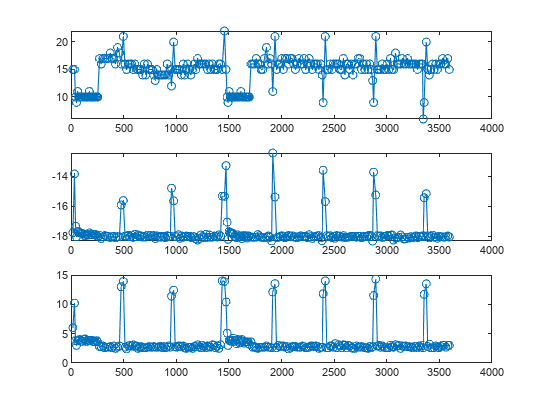

f1=zeros(1,length(locs)-1);
for i=1:length(locs)-1
    f1(i)=locs(i+1)-locs(i);
end
locs=locs(2:end);
figure 
subplot(311)
plot(locs,f1,'o-')
subplot(312)
plot(locs,x(3,:),'o-')
subplot(313)
plot(locs,x(1,:)-x(2,:),'o-')

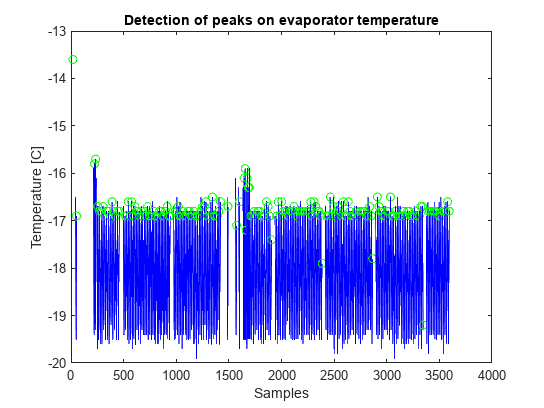

fridge_air_temp_p2p=x(1,:)-x(2,:);
indexContainer=cell(1);
indexContainer{1}=[];
set=1;
figure
% TF = isoutlier(f1);
TF = isoutlier(fridge_air_temp_p2p);

plot(locs(1),(X_filtered(2,locs(1))),'Marker','o',"Color",'green');hold on
for i=2:length(x)
    
    if (TF(i)==0)
        plot(locs(i-1):locs(i),(X_filtered(2,locs(i-1):locs(i))),"Color",'blue');
        plot(locs(i),(X_filtered(2,locs(i))),'Marker','o',"Color",'green');
        indexContainer{set}=[indexContainer{set},locs(i-1):locs(i)];
    else
        if TF(i-1)==0
            set=set+1;
            indexContainer{set}=[];
        end
    end
end
% plot(locs,(X_filtered(4,locs)),'Marker','o',"Color",'green');
hold off
title('Detection of peaks on evaporator temperature')
xlabel('Samples')
ylabel('Temperature [C]')

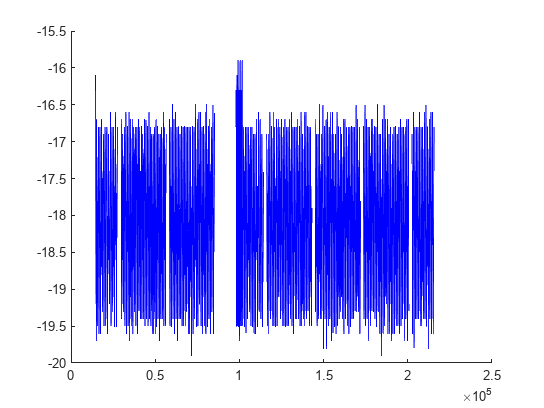

set=1;
for i = 1:length(indexContainer)
    if length(indexContainer{i})>60
        usableDataIndex{set}=indexContainer{i};
        set=set+1;
    end
end

figure
hold on
for i = 1:length(usableDataIndex)
% for i = 1:3
    plot(t(usableDataIndex{i}),X_filtered(2,usableDataIndex{i}),'b')
end
hold off

Regardless if we use the cycle length of p2p per cycle, the system picks up unwanted period.

If we use p2p, the period when the fridge was getting regularly opened gets picked up. If we use cycle lenght some of the cycles at the end of the stationary period get picked up even tho they already should be out.

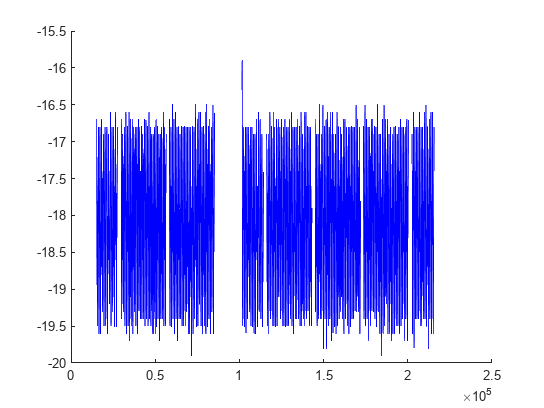

fridge_air_temp_p2p=x(1,:)-x(2,:);
indexContainer=cell(1);
indexContainer{1}=[];
set=1;
clear indexContainer
indexContainer=cell(1);
indexContainer{1}=[];
% figure
TF = isoutlier(f1);
TF2 = isoutlier(fridge_air_temp_p2p);

% plot(locs(1),(X_filtered(2,locs(1))),'Marker','o',"Color",'green');hold on
for i=2:length(x)
    
    if (TF(i)==0 && TF2(i)==0)
        % plot(locs(i-1):locs(i),(X_filtered(2,locs(i-1):locs(i))),"Color",'blue');
        % plot(locs(i),(X_filtered(2,locs(i))),'Marker','o',"Color",'green');
        indexContainer{set}=[indexContainer{set},locs(i-1):locs(i)];
    else
        if (TF(i-1)==0 || TF2(i-1)==0)
            set=set+1;
            indexContainer{set}=[];
        end
    end
end
% plot(locs,(X_filtered(4,locs)),'Marker','o',"Color",'green');
% hold off
% title('Detection of peaks on evaporator temperature')
% xlabel('Samples')
% ylabel('Temperature [C]')
set=1;
clear usableDataIndex
for i = 1:length(indexContainer)
    if length(indexContainer{i})>60
        usableDataIndex{set}=indexContainer{i};
        set=set+1;
    end
end

figure
hold on
for i = 1:length(usableDataIndex)
% for i = 1:3
    plot(t(usableDataIndex{i}),X_filtered(2,usableDataIndex{i}),'b')
end
hold off

Using both conditions, cycle lenght and p2p gave desired results.

Now using grphical analysys of the time plot and the cycle length per cyce we determine the times where the signal had different stationary parameters.

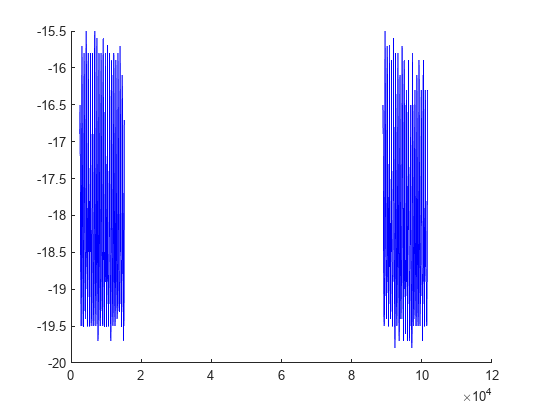

stat2ind={43:254;1483:1694};

figure
hold on
for i = 1:length(stat2ind)
    plot(t(stat2ind{i}),X_filtered(2,stat2ind{i}),'b')
end
hold off